# Welcome

- フォーラムを作ってディスカッションすることを推奨する

- 簡単なコピペでコードを修正できるような投稿は削除する

- ヒントを与えるようなコードや、テクニックのデモのためのコードはOK

Q：1行目ないし、1列目を0にするためのコードは？

A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


B=A;
A(:,1) = 0

A =      0     1     6
     0     5     7
     0     9     2


B(1,:) = 0

B =      0     0     0
     3     5     7
     4     9     2


# Introduction

## マシンラーニングとは？

アーサーサムエル曰く「コンピューターが明示的にプログラムされなくても学習できるようにする研究分野」

トムミッシェル曰く「Pによって測定されるTのタスクでのパフォーマンスがエクスペリエンスEで向上する場合、タスクTおよびパフォーマンス測定Pのクラスに関してエクスペリエンスEから学習すると言われています」

マシンラーニングは大別すると教師有無学習の2つに分類される

## 教師あり学習

データセットが与えられ、正しい出力がどのようなものか分かっている

入出力間に関係があるという考え

教師あり学習は分類問題と回帰問題に分けられる

### 回帰問題

- 「連続」値について取り扱う

- 与えられたデータを多項式等の関数として表現しようとする

- カーブフィッティング

- 人の写真が与えられてその人の年齢を予測する場合

### 分類問題

- 「離散」値について取り扱う

- 与えられたデータをカテゴリ別にマップしようとする

- 患者の腫瘍データが与えられてそれが悪性か良性か予測する場合

## 教師なし学習

- 与えられたデータはラベルがない

- 与えられたデータ間の関係性に基づいて構造を導く

- 予測結果に基づくFBはない

### クラスタリング

1,000,000個の異なる遺伝子のコレクションを取得し、これらの遺伝子を寿命、場所、役割などの異なる変数によって何らかの形で類似または関連するグループに自動的にグループ化する方法を見つけます

### 非クラスタリング

「カクテルパーティーアルゴリズム」を使用すると、混沌とした環境で構造を見つけることができます。 （つまり、カクテルパーティーでの音のメッシュから個々の声と音楽を識別する）

# Model and Cost Function

## モデル表現

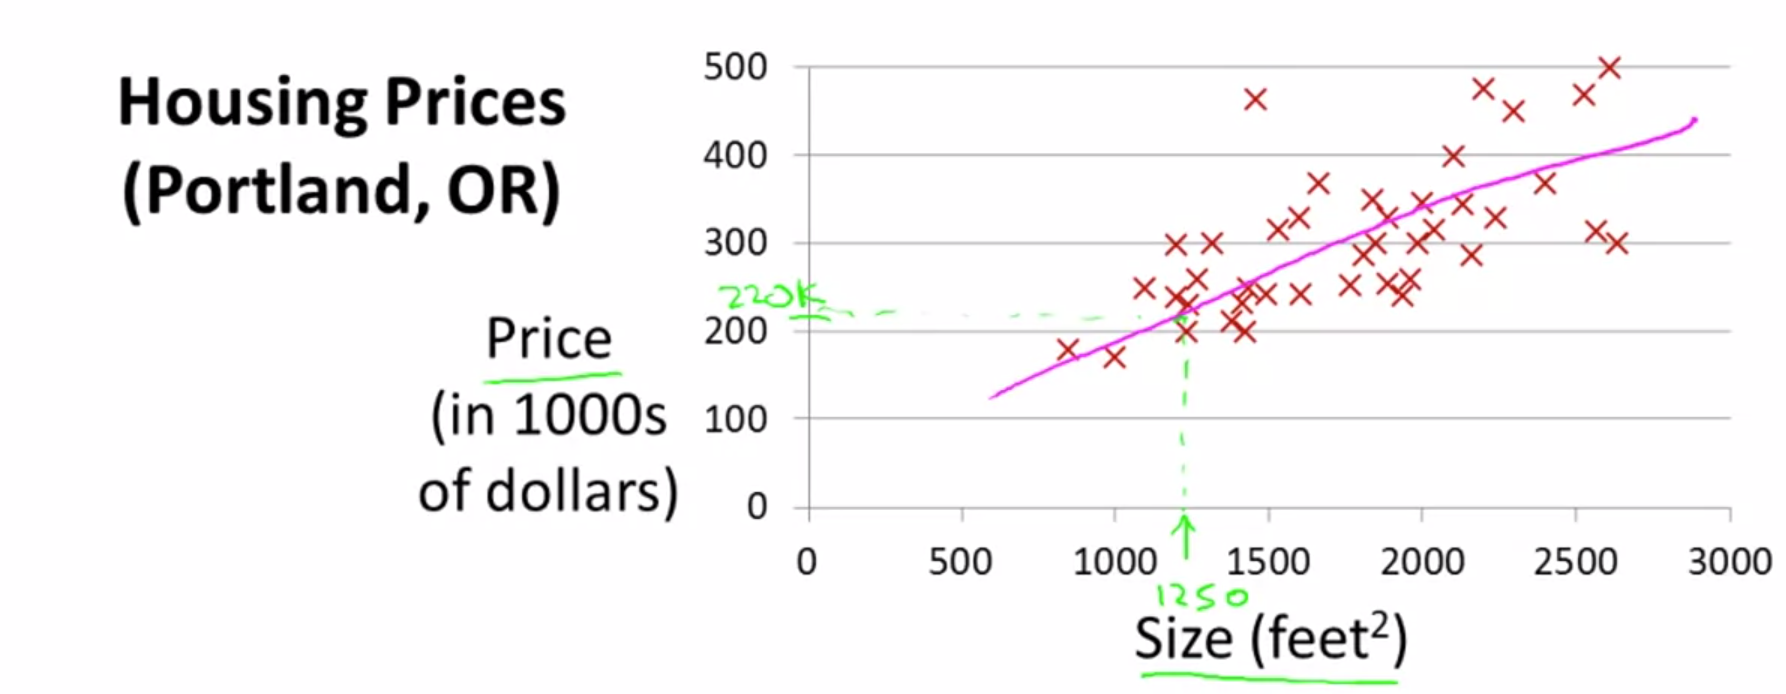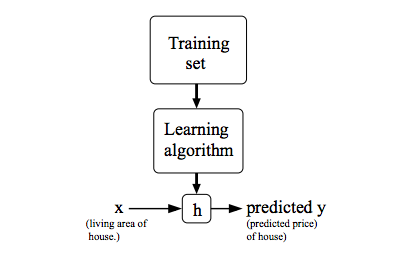

トレーニングデータから仮説関数h を作成する

x が入力されたとき、 h(x) から y を算出する

yが住宅価格のように連続値を取る場合、その学習問題を回帰問題と呼ぶ

(y が家かアパートかのように少数の離散値を取る場合、分類問題と呼ぶ)

## コスト関数

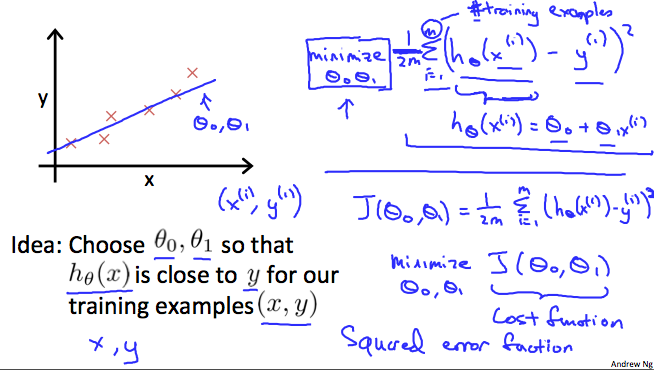

コスト関数を使用することで、仮説関数の精度を測定できる


$$J\left(\theta_0 ,\theta_1 \right)=\frac{1}{2m}\sum_{i=1}^m {\left({\overset{\wedge }{y} }_i -y_i \right)}^2 =\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta } \left(x_i \right)-y_i \right)}^2$$


この関数は「二乗誤差関数」または「平均二乗誤差」と呼ばれます。

二乗関数の微分項は(1/2)項を打ち消すため、勾配降下の計算の便宜上、平均は半分になります。

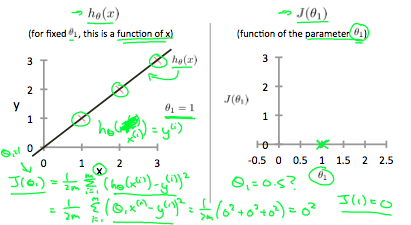

% The ; denotes we are going back to a new row.
A = [1, 2, 3; 4, 5, 6; 7, 8, 9; 10, 11, 12]

A =      1     2     3
     4     5     6
     7     8     9
    10    11    12



% Initialize a vector 
v = [1;2;3] 

v =      1
     2
     3



% Get the dimension of the matrix A where m = rows and n = columns
[m,n] = size(A)

m = 4

n = 3


% You could also store it this way
dim_A = size(A)

dim_A =      4     3



% Get the dimension of the vector v 
dim_v = size(v)

dim_v =      3     1



% Now let's index into the 2nd row 3rd column of matrix A
A_23 = A(2,3)

A_23 = 6


X = rand(5,4)

X =     0.5617    0.4279    0.1913    0.8070
    0.3057    0.5249    0.5888    0.1538
    0.4230    0.0786    0.1957    0.3549
    0.6527    0.2966    0.2160    0.9746
    0.4579    0.9383    0.8254    0.0917


y = rand(5,1)

y =     0.7301
    0.6364
    0.6528
    0.3863
    0.7784



theta = pinv(X' * X)*X'*y

theta =     2.2293
    0.1307
   -0.2067
   -0.8977


# コードチュートリアル1 : Basic Operations

5+6

ans = 11

3-2

ans = 1

5*8

ans = 40

10/2

ans = 5

1 == 2

ans = logical
   0


1 ~= 2

ans = logical
   1


1 && 0

ans = logical
   0


1 || 0

ans = logical
   1


xor(1,0)

ans = logical
   1


c = (3>=1)

c = logical
   1


c

c = logical
   1


a = pi;
disp(a)

    3.1416



disp(sprintf('2 decimals: %0.2f',a))

2 decimals: 3.14


fprintf('2 decimals: %0.2f\n',a)

2 decimals: 3.14



fprintf('2 decimals: %0.6f\n',a)

2 decimals: 3.141593



A = [1 2; 3 4; 5 6]

A =      1     2
     3     4
     5     6


v1 = [1 2 3]

v1 =      1     2     3


v2 = [1; 2; 3;]

v2 =      1
     2
     3


v3 = 1:0.1:2

v3 =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000



ones(2,3)

ans =      1     1     1
     1     1     1


B = 2*ones(2,3)

B =      2     2     2
     2     2     2



rand(1,3)

ans =     0.0039    0.4931    0.9176


rand(1,3)

ans =     0.2516    0.9072    0.7815



randn(1,3)

ans =     0.1140   -0.2281    1.0028


randn(1,3)

ans =    -1.0391    1.2158   -0.3330



w1 = randn(1,10000)

w1 =    -1.2077    0.2520   -0.2597    1.1684    1.1135    0.7035   -0.6328    0.7764   -0.3153    1.5883    0.1515   -0.3515   -1.8699   -1.4373    1.4953    1.4301    0.5226    0.2344    0.8648    1.9556    0.2984    1.7780   -0.4085    1.0434    1.2228   -1.2571   -0.4306   -0.4187   -0.3625   -0.5012   -0.3311   -0.3493    0.4214    0.4629    0.4171   -0.1348    0.2497   -1.3066    0.3926   -0.5682   -0.7236   -0.1650   -0.7505    0.7278   -0.0422   -0.4113    0.4332   -0.0572    1.6967   -0.4769


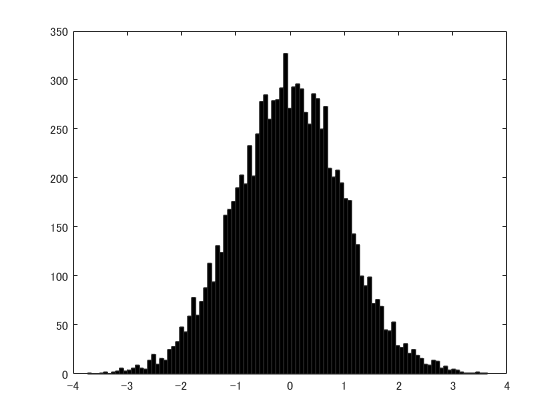

hist(w1,100)


w2 = rand(1,10000)

w2 =     0.0422    0.7144    0.3691    0.5243    0.4659    0.2309    0.6304    0.7569    0.9797    0.2866    0.1211    0.2381    0.0687    0.5890    0.3858    0.4584    0.9910    0.5121    0.6241    0.6255    0.3790    0.0856    0.5407    0.9951    0.6752    0.4602    0.2416    0.8648    0.2750    0.6277    0.2158    0.1338    0.2574    0.0200    0.7854    0.1587    0.9124    0.8219    0.1519    0.2604    0.7520    0.0825    0.0179    0.8406    0.2446    0.1987    0.5889    0.7556    0.9299    0.8546


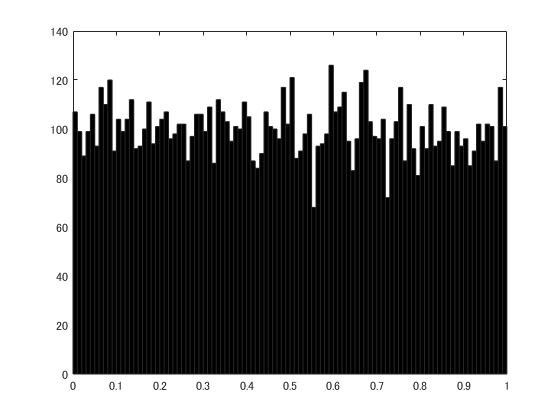

hist(w2,100)


eye(4)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



help eye

eye - 単位行列

    この MATLAB 関数 はスカラー 1 を返します。

    I = eye
    I = eye(n)
    I = eye(n,m)
    I = eye(sz)
    I = eye(classname)
    I = eye(n,classname)
    I = eye(n,m,classname)
    I = eye(sz,classname)
    I = eye('like',p)
    I = eye(n,'like',p)
    I = eye(n,m,'like',p)
    I = eye(sz,'like',p)

    参考 <a href="https://www.mathworks.com/help/releases/R2019b/matlab/ref/ones.html">ones</a>, <a href="https://www.mathworks.com/help/releases/R2019b/matlab/ref/speye.html">speye</a>, <a href="https://www.mathworks.com/help/releases/R2019b/matlab/ref/zeros.html">zeros</a>

    eye のドキュメンテーション



# コードチュートリアル2 : Moving Data Around

A

A =      1     2
     3     4
     5     6


size(A)

ans =      3     2


sz = size(A)

sz =      3     2


size(A,1)

ans = 3

size(A,1) == sz(1,1)

ans = logical
   1



v = [1 2 3 4]

v =      1     2     3     4


length(v)

ans = 4


pwd

ans = 'D:\Matlab\matlabdrive'


%load featuresX.dat

who


変数:

A      Aeye   B1     C1     X      ans    c      comb2  dim_v  ind    m      r      t      v      v2     val    w2     y1     
A_23   B      B2     C2     a      b      comb1  dim_A  i      j      n      sz     theta  v1     v3     w1     y      y2     



whos

  Name       Size               Bytes  Class      Attributes

  A          3x2                   48  double               
  A_23       1x1                    8  double               
  Aeye       9x9                  648  double               
  B          2x3                   48  double               
  B1         3x1                   24  double               
  B2         1x4                   32  double               
  C1         3x5                  120  double               
  C2         4x4                  128  double               
  X          5x4                  160  double               
  a          1x1                    8  double               
  ans        1x21                  42  char                 
  b          1x1                    8  double               
  c          1x1                    1  logical              
  comb1      3x3                   72  double               
  comb2      3x3                   72  double               
  dim_A      1x2       


clear

who

A = eye(3)

A =      1     0     0
     0     1     0
     0     0     1



who


変数:

A  




save hello.mat A
save hello.txt A -ascii

A(2,:)

ans =      0     1     0


A(:,1)

ans =      1
     0
     0


A(:,:)

ans =      1     0     0
     0     1     0
     0     0     1


A([1 3],:)

ans =      1     0     0
     0     0     1



A(:,2) = [2; 3; 4;]

A =      1     2     0
     0     3     0
     0     4     1



A = [A, [5; 6; 7;]]

A =      1     2     0     5
     0     3     0     6
     0     4     1     7



A(:)

ans =      1
     0
     0
     2
     3
     4
     0
     0
     1
     5



B1 = [10; 11; 12;]

B1 =     10
    11
    12


B2 = [10 11 12 13]

B2 =     10    11    12    13


C1 = [A, B1]

C1 =      1     2     0     5    10
     0     3     0     6    11
     0     4     1     7    12


C2 = [A; B2]

C2 =      1     2     0     5
     0     3     0     6
     0     4     1     7
    10    11    12    13


# コードチュートリアル3 : Computing on Data

A = [1 2; 3 4; 5 6;]

A =      1     2
     3     4
     5     6


B = [11 12; 13 14; 15 16;]

B =     11    12
    13    14
    15    16



A .* B

ans =     11    24
    39    56
    75    96


A .^ 2

ans =      1     4
     9    16
    25    36



v = [1; 2; 3;]

v =      1
     2
     3


1 ./ v

ans =     1.0000
    0.5000
    0.3333


1 ./ A

ans =     1.0000    0.5000
    0.3333    0.2500
    0.2000    0.1667


log(v)

ans =          0
    0.6931
    1.0986


-v

ans =     -1
    -2
    -3


abs(-v)

ans =      1
     2
     3


v + 1

ans =      2
     3
     4


v + ones(length(v),1)

ans =      2
     3
     4



A

A =      1     2
     3     4
     5     6


A'

ans =      1     3     5
     2     4     6


(A')'

ans =      1     2
     3     4
     5     6



a = [1 15 2 0.5];
val = max(a)

val = 15

[val, ind] = max(a)

val = 15

ind = 2

max(A)

ans =      5     6


a < 3

ans = 1×4 の logical 配列
   1   0   1   1


find(a < 3)

ans =      1     3     4



A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


[r,c] = find(A >= 7)

r =      1
     3
     2


c =      1
     2
     3


[r,c] = find(A >= 1)

r =      1
     2
     3
     1
     2
     3
     1
     2
     3


c =      1
     1
     1
     2
     2
     2
     3
     3
     3



a

a =     1.0000   15.0000    2.0000    0.5000


sum(a)

ans = 18.5000

prod(a)

ans = 15

floor(a)

ans =      1    15     2     0


ceil(a)

ans =      1    15     2     1



rand(3)

ans =     0.1682    0.3009    0.7733
    0.7399    0.3414    0.0859
    0.5493    0.0222    0.6966


comb1 = max(rand(3),rand(3))

comb1 =     0.6076    0.9715    0.1108
    0.2729    0.5908    0.9464
    0.6434    0.3885    0.6221


comb2 = max(rand(3),eye(3))

comb2 =     1.0000    0.8375    0.9214
    0.5495    1.0000    0.0908
    0.1465    0.4517    1.0000



A =magic(3)

A =      8     1     6
     3     5     7
     4     9     2


max(A,[], 1)

ans =      8     9     7


max(A,[],2)

ans =      8
     7
     9


max(comb1,[],1)

ans =     0.6434    0.9715    0.9464


max(comb1,[],2)

ans =     0.9715
    0.9464
    0.6434


max(A)

ans =      8     9     7


[val, ind] = max(A)

val =      8     9     7


ind =      1     3     2


max(max(A))

ans = 9

max(A(:))

ans = 9


A = magic(9)

A =     47    58    69    80     1    12    23    34    45
    57    68    79     9    11    22    33    44    46
    67    78     8    10    21    32    43    54    56
    77     7    18    20    31    42    53    55    66
     6    17    19    30    41    52    63    65    76
    16    27    29    40    51    62    64    75     5
    26    28    39    50    61    72    74     4    15
    36    38    49    60    71    73     3    14    25
    37    48    59    70    81     2    13    24    35


sum(A,1)

ans =    369   369   369   369   369   369   369   369   369


sum(A,2)

ans =    369
   369
   369
   369
   369
   369
   369
   369
   369


Aeye = A .* eye(9)

Aeye =     47     0     0     0     0     0     0     0     0
     0    68     0     0     0     0     0     0     0
     0     0     8     0     0     0     0     0     0
     0     0     0    20     0     0     0     0     0
     0     0     0     0    41     0     0     0     0
     0     0     0     0     0    62     0     0     0
     0     0     0     0     0     0    74     0     0
     0     0     0     0     0     0     0    14     0
     0     0     0     0     0     0     0     0    35


sum(Aeye(:))

ans = 369


flipud(eye(9))

ans =      0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     1     0     0     0     0
     0     0     0     1     0     0     0     0     0
     0     0     1     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0


Aeye = A.* flipud(eye(9))

Aeye =      0     0     0     0     0     0     0     0    45
     0     0     0     0     0     0     0    44     0
     0     0     0     0     0     0    43     0     0
     0     0     0     0     0    42     0     0     0
     0     0     0     0    41     0     0     0     0
     0     0     0    40     0     0     0     0     0
     0     0    39     0     0     0     0     0     0
     0    38     0     0     0     0     0     0     0
    37     0     0     0     0     0     0     0     0


sum(Aeye(:))

ans = 369


A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


pinv(A)

ans =     0.1472   -0.1444    0.0639
   -0.0611    0.0222    0.1056
   -0.0194    0.1889   -0.1028


A * A'

ans =    101    71    53
    71    83    71
    53    71   101


A * pinv(A)

ans =     1.0000   -0.0000    0.0000
    0.0000    1.0000         0
   -0.0000    0.0000    1.0000


pinv(A) * A

ans =     1.0000    0.0000   -0.0000
   -0.0000    1.0000    0.0000
    0.0000   -0.0000    1.0000


# コードチュートリアル4 : Plot

t = [0:0.01:1]

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


y1 = sin(2*pi*4*t)

y1 =          0    0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    0.9823    0.9048    0.7705    0.5878    0.3681    0.1253   -0.1253   -0.3681   -0.5878   -0.7705   -0.9048   -0.9823   -0.9980   -0.9511   -0.8443   -0.6845   -0.4818   -0.2487   -0.0000    0.2487    0.4818    0.6845    0.8443


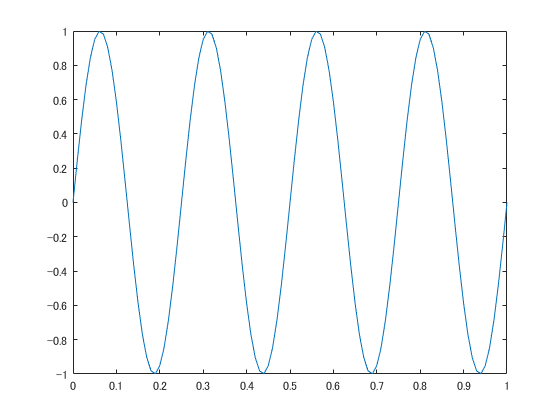

plot(t,y1)

y2 = cos(2*pi*4*t)

y2 =     1.0000    0.9686    0.8763    0.7290    0.5358    0.3090    0.0628   -0.1874   -0.4258   -0.6374   -0.8090   -0.9298   -0.9921   -0.9921   -0.9298   -0.8090   -0.6374   -0.4258   -0.1874    0.0628    0.3090    0.5358    0.7290    0.8763    0.9686    1.0000    0.9686    0.8763    0.7290    0.5358


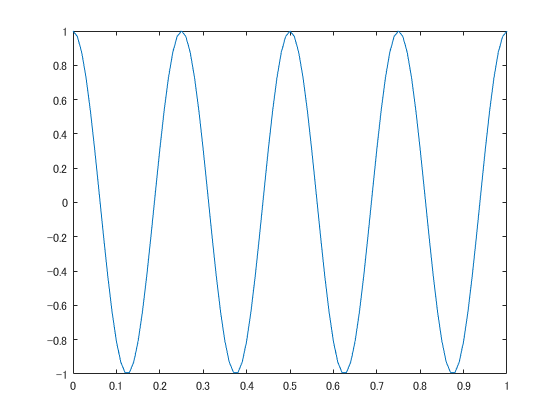

plot(t,y2)

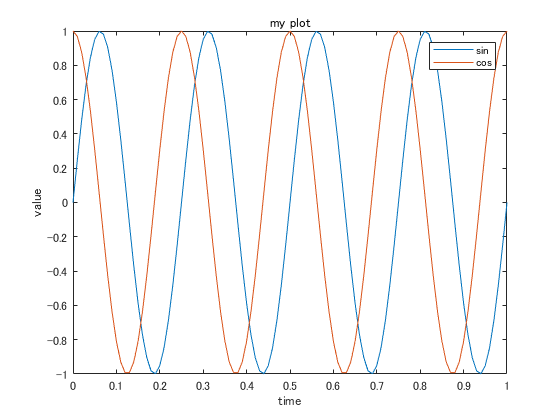


plot(t,y1)
hold on
plot(t,y2)
xlabel('time')
ylabel('value')
legend('sin','cos')
title('my plot')
hold off

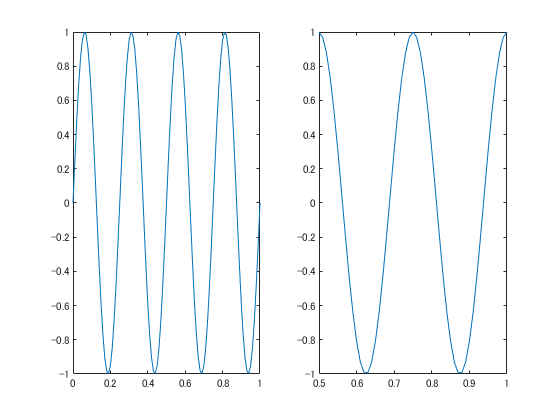

%print -dpng 'myPlot.png'

subplot(1,2,1)
plot(t,y1)
subplot(1,2,2)
plot(t,y2)
axis([0.5 1 -1 1])

clf


A = magic(5)

A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


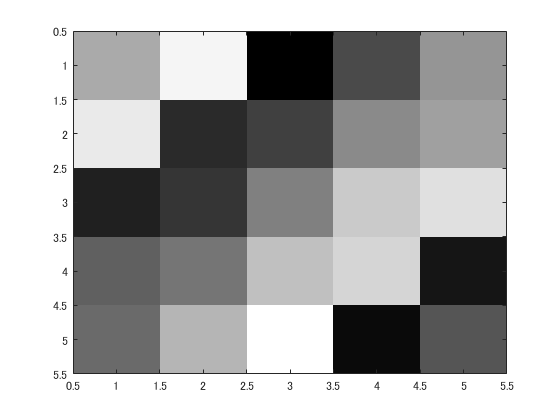

imagesc(A)

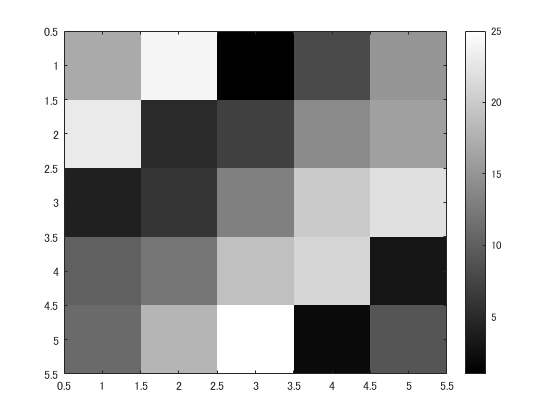

imagesc(A), colorbar, colormap gray

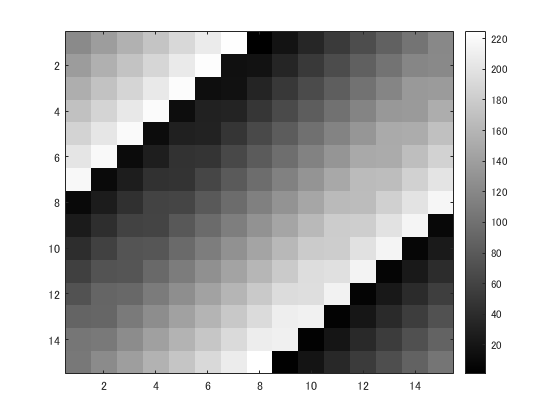

imagesc(magic(15)), colorbar, colormap gray


a=1, b=2, c=3

a = 1

b = 2

c = 3

a=1; b=2; c=3;

# コードチュートリアル4 : for, while, if statement

v = zeros(10,1)

v =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i=1:10
    v(i) = 2^i
end

v =      2
     0
     0
     0
     0
     0
     0
     0
     0
     0


v =      2
     4
     0
     0
     0
     0
     0
     0
     0
     0


v =      2
     4
     8
     0
     0
     0
     0
     0
     0
     0


v =      2
     4
     8
    16
     0
     0
     0
     0
     0
     0


v =      2
     4
     8
    16
    32
     0
     0
     0
     0
     0


v =      2
     4
     8
    16
    32
    64
     0
     0
     0
     0


v =      2
     4
     8
    16
    32
    64
   128
     0
     0
     0


v =      2
     4
     8
    16
    32
    64
   128
   256
     0
     0


v =      2
     4
     8
    16
    32
    64
   128
   256
   512
     0


v =            2
           4
           8
          16
          32
          64
         128
         256
         512
        1024



i = 1;
while i <= 5
    v(i) = 100;
    i = i+1;
end
v

v =          100
         100
         100
         100
         100
          64
         128
         256
         512
        1024



i = 1;
while true
    v(i) = 999;
    i = i+1;
    if i == 6
        break
    end
end
v

v =          999
         999
         999
         999
         999
          64
         128
         256
         512
        1024



v(1) = 2;
if v(1) == 1
    disp('The value is 1')
elseif v(1) == 2
    disp('The value is 2')
else
    disp('The value is not 1 or 2')
end

The value is 2



squareThisNumber(5)

ans = 25

[a,b] = squareAndCubeThisNumber(5)

a = 25

b = 125


X = [1 1; 1 2; 1 3;]

X =      1     1
     1     2
     1     3


y = [1; 2; 3;]

y =      1
     2
     3


theta = [0; 1;]

theta =      0
     1


size(X,1)

ans = 3


j = costFunctionJ(X, y, theta)

j = 0


theta = [0; 0;]

theta =      0
     0


j = costFunctionJ(X, y, theta)

j = 2.3333